## **Base Station Site**

Create a transmitter site on South Uncanoonuc Mountain in Goffstown, New Hampshire, US. The mountain is home to several transmitting facilities that serve the area. Define the transmitter site to represent a base station transmitting at 28 GHz with 1 Watt of power.

fq = 28e9; % 28 GHz
antHeight = 25; % m
txPowerDBm = 64; % Total transmit power in dBm
txPower = 10.^((txPowerDBm-30)/10); % Convert dBm to W
isd = 500;

## **Load JSON file**

NetworkNodes = jsondecode(fileread("Network\Myopic-Network.json"));
UnassignedNodes = jsondecode(fileread("Network\Myopic-Unassigned.json"));

## **Create Cellsites**

Each cell site has three transmitters corresponding to each cell. Create arrays to define the names, latitudes, longitudes, and antenna angles of each cell transmitter.

network = fieldnames(NetworkNodes);
unassigned = fieldnames(UnassignedNodes);
rxs = {};
txs = {};

for s = 1:length(network)
    tx = txsite("Name", NetworkNodes.(network{s}).Name, ...
    "Latitude", NetworkNodes.(network{s}).Position(2), ...
    "Longitude", NetworkNodes.(network{s}).Position(1), ...
    "AntennaHeight",antHeight,...
    "TransmitterPower",1, ...
    "TransmitterFrequency",fq);
    txs = [txs, tx];
    
    members = fieldnames(NetworkNodes.(network{s}).MEMBERS);
    for k = 1:length(members)
        rx = rxsite("Name", NetworkNodes.(network{s}).MEMBERS.(members{k}).Name, ...
        "Latitude", NetworkNodes.(network{s}).MEMBERS.(members{k}).Position(2), ...
        "Longitude", NetworkNodes.(network{s}).MEMBERS.(members{k}).Position(1), ...
        "AntennaHeight",antHeight);
        rxs = [rxs, rx]
    end
end

rxs =   rxsite with properties:

                   Name: 'St Matthews School'
               Latitude: -26.2600
              Longitude: 27.8812
                Antenna: [1×1 dipole]
           AntennaAngle: 0
          AntennaHeight: 25
             SystemLoss: 0
    ReceiverSensitivity: -100


rxs =   1×2 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×3 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×4 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×5 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×6 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×7 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×8 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×9 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×10 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×11 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×12 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×13 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×14 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×15 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×16 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×17 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×18 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×19 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×20 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×21 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×22 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×23 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×24 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×25 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×26 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×27 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×28 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×29 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×30 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×31 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×32 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×33 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×34 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×35 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×36 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×37 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×38 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×39 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×40 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×41 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×42 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×43 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×44 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×45 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×46 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×47 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×48 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×49 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×50 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×51 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×52 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×53 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×54 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×55 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×56 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×57 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×58 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×59 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×60 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×61 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×62 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×63 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×64 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×65 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×66 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×67 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×68 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×69 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×70 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×71 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×72 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×73 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×74 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×75 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×76 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity


rxs =   1×77 rxsite array with properties:

    Name
    Latitude
    Longitude
    Antenna
    AntennaAngle
    AntennaHeight
    SystemLoss
    ReceiverSensitivity



for s = 1:length(unassigned)
    rx = rxsite("Name", UnassignedNodes.(unassigned{s}).Name, ...
    "Latitude", UnassignedNodes.(unassigned{s}).Position(2), ...
    "Longitude", UnassignedNodes.(unassigned{s}).Position(1), ...
    "AntennaHeight",antHeight);
    rxs = [rxs, rx];
end
    
% Launch Site Viewer
viewer = siteviewer;

% Show sites on a map
show(txs);
show(rxs);
viewer.Basemap = 'openstreetmap';

## Create Antenna Element

Section 8.5 of ITU-R report [1] defines antenna characteristics for base station antennas. The antenna is modeled as having one or more antenna panels, where each panel has one or more antenna elements. Use Phased Array System Toolbox to implement the antenna element pattern defined in the report.

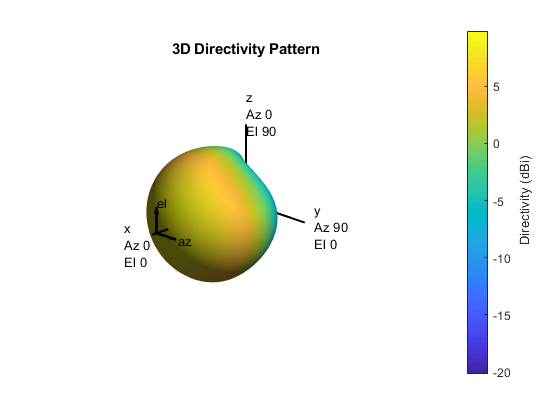

% Define pattern parameters
azvec = -180:180;
elvec = -90:90;
Am = 30; % Maximum attenuation (dB)
tilt = 0; % Tilt angle
az3dB = 65; % 3 dB bandwidth in azimuth
el3dB = 65; % 3 dB bandwidth in elevation

% Define antenna pattern
[az,el] = meshgrid(azvec,elvec);
azMagPattern = -12*(az/az3dB).^2;
elMagPattern = -12*((el-tilt)/el3dB).^2;
combinedMagPattern = azMagPattern + elMagPattern;
combinedMagPattern(combinedMagPattern<-Am) = -Am; % Saturate at max attenuation
phasepattern = zeros(size(combinedMagPattern));

% Create antenna element
antennaElement = phased.CustomAntennaElement(...
    'AzimuthAngles',azvec, ...
    'ElevationAngles',elvec, ...
    'MagnitudePattern',combinedMagPattern, ...
    'PhasePattern',phasepattern);
   
% Display radiation pattern
f = figure;
pattern(antennaElement,fq);

## Display SINR Map for Single Antenna Element

Visualize SINR for the test scenario using a single antenna element and the free space propagation model. For each colored location on the map, the signal source is the cell with the greatest signal strength, and all other cells are sources of interference.

% Assign the antenna element for each cell transmitter
for tx = txs
    tx.Antenna = antennaElement;
end

% Define receiver parameters using Table 8-2 (b) of Report ITU-R M.[IMT-2020.EVAL] 
bw = 20e6; % 20 MHz bandwidth
rxNoiseFigure = 7; % dB
rxNoisePower = -174 + 10*log10(bw) + rxNoiseFigure;
rxGain = 0; % dBi
rxAntennaHeight = 1.5; % m

## Create 8-by-8 Rectangular Antenna Array

Define an antenna array to increase directional gain and increase peak SINR values. Use Phased Array System Toolbox to create an 8-by-8 uniform rectangular array.

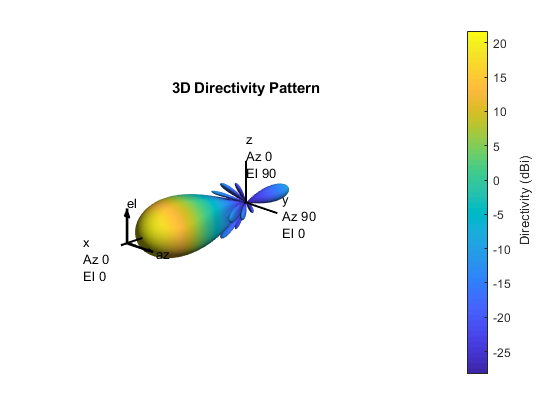

% Define array size
nrow = 8;
ncol = 8;

% Define element spacing
lambda = physconst('lightspeed')/fq;
drow = lambda/2;
dcol = lambda/2;

% Define taper to reduce sidelobes 
dBdown = 30;
taperz = chebwin(nrow,dBdown);
tapery = chebwin(ncol,dBdown);
tap = taperz*tapery.'; % Multiply vector tapers to get 8-by-8 taper values

% Create 8-by-8 antenna array
cellAntenna = phased.URA('Size',[nrow ncol], ...
    'Element',antennaElement, ...
    'ElementSpacing',[drow dcol], ...
    'Taper',tap, ...
    'ArrayNormal','x');
    
% Display radiation pattern
f = figure;
pattern(cellAntenna,fq);

## Create 3-by-3 Receiver Site Antenna Array

Create a 3-by-3 rectangular array from a reflector-backed vertical dipole antenna element. At each receiver site, point the array toward the base station and plot the radiation pattern on the map.

rxElement = reflectorDipoleElement(fq);

% Define array size
nrxrow = 3;
nrxcol = 3;
    
% Define element spacing
lambda = physconst("lightspeed")/fq;
drow = lambda/2;
dcol = lambda/2;

% Create antenna array
rxarray = phased.URA("Size",[nrxrow nrxcol], ...
    "Element",rxElement, ...
    "ElementSpacing",[drow dcol]);

% Assign array to each receiver site and point toward base station
for rx = rxs
    rx.Antenna = rxarray;
    
    tx = findTX(rx, txs, network, NetworkNodes);
    rx.AntennaAngle = angle(rx, tx);    
end

## Use Rectangular Patch Antenna as Array Element

The analysis above used an antenna element that was defined using the equations specified in the ITU-R report [1]. The antenna element needs to provide a maximum gain of 9.5 dBi and a front-to-back ratio of approximately 30 dB. Now replace the equation-based antenna element definition with a real antenna model using a standard half-wavelength rectangular microstrip patch antenna. The antenna element provides a gain of about 9 dBi, although with a lower front-to-back ratio. 

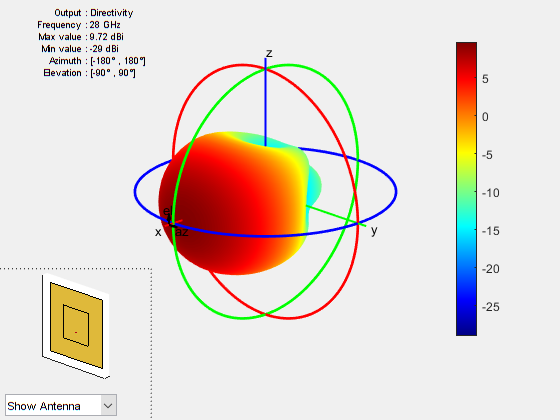

% Design half-wavelength rectangular microstrip patch antenna
patchElement = design(patchMicrostrip,fq);
patchElement.Width = patchElement.Length;
patchElement.Tilt = 90;
patchElement.TiltAxis = [0 1 0];

% Display radiation pattern
f = figure;
pattern(patchElement,fq)

## Display SINR Map using the Patch Antenna Element in the 8-by-8 Array

Update the SINR map for the Close-In propagation model [3] using the patch antenna as the array element. This analysis should capture the effect of deviations from an equation-based antenna specification as per the ITU-R report [1], including:

- Variations in peak gain

- Variations in pattern symmetry with spatial angles

- Variations in front-to-back ratios

% Assign the patch antenna as the array element
cellAntenna.Element = patchElement;

% Display SINR map
if isvalid(f)
    close(f)
end
sinr(txs,'close-in',...
    'ReceiverGain',rxGain, ...
    'ReceiverAntennaHeight',rxAntennaHeight, ...
    'ReceiverNoisePower',rxNoisePower, ...    
    'MaxRange',isd, ...
    'Resolution',isd/20)

## Add Path Loss Impairments

Additional attenuation of the signal occurs due to foliage and weather. Use Weissberger's model [3] to estimate path loss due to foliage, and use the rain propagation model to estimate signal strength in heavy rainfall. In the presence of path loss impairments, the estimated signal strength becomes weak and drops below the receiver sensitivity of -84 dBm.

% Assume that propagation path travels through 25 m of foliage
foliageDepth = 25;
L = 1.33*((fq/1e9)^0.284)*foliageDepth^0.588; % Weissberger model for d > 14
disp("Path loss due to foliage: " + L + " dB")

Path loss due to foliage: 22.7422 dB


% Assign foliage loss as static SystemLoss on each receiver site
for rx = rxs
    rx.SystemLoss = L;
end

% Compute signal strength with foliage loss
for rx = rxs
    rx.SystemLoss = L;
    
    tx = findTX(rx, txs, network, NetworkNodes);
    ss = sigstrength(rx,tx,"freespace");
    disp("Signal strength at " + rx.Name + ":")
    disp(ss + " dBm")
end

Signal strength at St Matthews School:


-120.5918 dBm


Signal strength at Fundani Primary School:


-135.2846 dBm


Signal strength at Mooki Memorial College:


-102.2976 dBm


Signal strength at P J Simelane Secondary School:


-128.9269 dBm


Signal strength at Prestige College:


-140.7279 dBm


Signal strength at Sekwati Primary School:


-127.0793 dBm


Signal strength at Adelaide Thambo School:


-111.5666 dBm


Signal strength at Amadoda Ayasebenza (PTY) LTD:


-101.4542 dBm


Signal strength at Enkanyezini Primary School:


-124.4645 dBm


Signal strength at Curtis Nkondo School Of Specialization:


-134.3791 dBm


Signal strength at Luyolo Higher Primary School:


-133.6459 dBm


Signal strength at Jabavu East Primary School:


-132.9883 dBm


Signal strength at Peter Lengene Community Learning Centre:


-102.1801 dBm


Signal strength at Makhoarane Primary School:


-126.0269 dBm


Signal strength at Daliwonga Secondary School:


-113.2627 dBm


Signal strength at Protea Glen College:


-132.8071 dBm


Signal strength at Emadlelweni Primary School:


-99.5281 dBm


Signal strength at St Angela's Primary School:


-127.2738 dBm


Signal strength at Mambo Primary School:


-125.2741 dBm


Signal strength at Zibambele Lower Primary School:


-133.742 dBm


Signal strength at DSJ Primary School:


-133.1852 dBm


Signal strength at The Plumbing Academy:


-91.4175 dBm


Signal strength at Ibhongo Secondary School:


-92.9039 dBm


Signal strength at Forte Secondary School:


-127.7739 dBm


Signal strength at Protea South Primary School:


-133.4108 dBm


Signal strength at Teacher Development Centre (Central District D14):


-120.8302 dBm


Signal strength at Moletsane High School:


-127.5233 dBm


Signal strength at Heerengracht Primary School:


-111.4998 dBm


Signal strength at WO BIBLE COLLEGE:


-121.4315 dBm


Signal strength at Altmont Technical High School:


-133.1304 dBm


Signal strength at BHUKULANI SENIOR SCONDARY SCHOOL:


-125.3288 dBm


Signal strength at Vukazenzele Primary School:


-113.2511 dBm


Signal strength at Johannesburg Bible College:


-101.9228 dBm


Signal strength at Emndeni Primary School:


-134.21 dBm


Signal strength at Thabisang Primary School:


-108.9902 dBm


Signal strength at Jabavu Oos Primary School:


-108.1684 dBm


Signal strength at Nurses Home:


-112.229 dBm


Signal strength at Naledi High School:


-101.1163 dBm


Signal strength at Rishile Lower Primary School:


-108.2476 dBm


Signal strength at HB Technology:


-101.8949 dBm


Signal strength at Fosta Records:


-109.7265 dBm


Signal strength at Impumelelo Junior Primary School:


-95.8094 dBm


Signal strength at Curro Academy Protea Glen Independent School:


-118.2948 dBm


Signal strength at Itemogele Primary School:


-119.3369 dBm


Signal strength at BTC-Soweto:


-108.4362 dBm


Signal strength at Melane Academy:


-107.8853 dBm


Signal strength at Izipho Zomphakathi Multiskills:


-97.2957 dBm


Signal strength at Molaetsa Primary School:


-102.7665 dBm


Signal strength at Nqobile Mhaleni:


-110.5439 dBm


Signal strength at Rebone Primary School:


-129.2473 dBm


Signal strength at Tlholohelo Primary School:


-112.0985 dBm


Signal strength at Megatong Primary School:


-92.0769 dBm


Signal strength at Nghunghunyani Comprehensive School:


-100.1727 dBm


Signal strength at South West College:


-106.6142 dBm


Signal strength at South West Gauteng College Head Office:


-96.5148 dBm


Signal strength at LechekoPowerYourMind:


-111.1089 dBm


Signal strength at Esiyalwini Junior Secondary School:


-114.1384 dBm


Signal strength at Lebo Sibi:


-134.5674 dBm


Signal strength at Enkolweni Primary School:


-127.6563 dBm


Signal strength at Bopasenatla Secondary School:


-108.1534 dBm


Signal strength at Lekang Primary School:


-119.4699 dBm


Signal strength at Tshilidzi Primary School:


-127.718 dBm


Signal strength at Mveledzandivho Primary School:


-124.2466 dBm


Signal strength at Boston City Campus & Business College - Maponya Mall:


-102.7224 dBm


Signal strength at Pq vundla:


-138.949 dBm


Signal strength at Pace Community College:


-131.2635 dBm


Signal strength at Chris Hani Baragwanath Nursing College:


-107.2964 dBm


Signal strength at Anchor High School:


-114.802 dBm


Signal strength at Entandweni Primary School:


-131.5808 dBm


Signal strength at Vuwani Secondary School:


-103.5803 dBm


Signal strength at Slovoville Primary School:


-138.0236 dBm


Signal strength at Thulare Secondary School:


-106.5512 dBm


Signal strength at Thaba Jabula Secondary School:


-107.6339 dBm


Signal strength at Ditau Primary School:


-108.853 dBm


Signal strength at Tetelo Secondary School:


-116.9957 dBm


Signal strength at Community Matric Learning Centre:


-110.6861 dBm


Signal strength at Mapetla High School:


-92.5886 dBm



% Compute signal strength with foliage loss and heavy rain, which is between
% 4 mm and 16 mm per hour. Reference: http://wiki.sandaysoft.com/a/Rain_measurement
rainpm = propagationModel('rain','RainRate',16);
for rx = rxs
    
    tx = findTX(rx, txs, network, NetworkNodes);
    ss = sigstrength(rx,tx,rainpm);
    disp("Signal strength at " + rx.Name + ":")
    disp(ss + " dBm")
end

Signal strength at St Matthews School:


-125.3202 dBm


Signal strength at Fundani Primary School:


-150.5141 dBm


Signal strength at Mooki Memorial College:


-112.8082 dBm


Signal strength at P J Simelane Secondary School:


-137.0172 dBm


Signal strength at Prestige College:


-165.2857 dBm


Signal strength at Sekwati Primary School:


-133.7495 dBm


Signal strength at Adelaide Thambo School:


-116.05 dBm


Signal strength at Amadoda Ayasebenza (PTY) LTD:


-111.3692 dBm


Signal strength at Enkanyezini Primary School:


-129.5021 dBm


Signal strength at Curtis Nkondo School Of Specialization:


-148.3546 dBm


Signal strength at Luyolo Higher Primary School:


-146.668 dBm


Signal strength at Jabavu East Primary School:


-145.2006 dBm


Signal strength at Peter Lengene Community Learning Centre:


-113.3015 dBm


Signal strength at Makhoarane Primary School:


-138.278 dBm


Signal strength at Daliwonga Secondary School:


-123.17 dBm


Signal strength at Protea Glen College:


-144.8049 dBm


Signal strength at Emadlelweni Primary School:


-103.3175 dBm


Signal strength at St Angela's Primary School:


-140.4325 dBm


Signal strength at Mambo Primary School:


-130.778 dBm


Signal strength at Zibambele Lower Primary School:


-146.8874 dBm


Signal strength at DSJ Primary School:


-146.1937 dBm


Signal strength at The Plumbing Academy:


-94.4335 dBm


Signal strength at Ibhongo Secondary School:


-95.6111 dBm


Signal strength at Forte Secondary School:


-142.2763 dBm


Signal strength at Protea South Primary School:


-146.1384 dBm


Signal strength at Teacher Development Centre (Central District D14):


-125.9761 dBm


Signal strength at Moletsane High School:


-134.5155 dBm


Signal strength at Heerengracht Primary School:


-126.2654 dBm


Signal strength at WO BIBLE COLLEGE:


-126.6072 dBm


Signal strength at Altmont Technical High School:


-145.5146 dBm


Signal strength at BHUKULANI SENIOR SCONDARY SCHOOL:


-130.8616 dBm


Signal strength at Vukazenzele Primary School:


-117.8865 dBm


Signal strength at Johannesburg Bible College:


-112.5434 dBm


Signal strength at Emndeni Primary School:


-147.9627 dBm


Signal strength at Thabisang Primary School:


-130.1937 dBm


Signal strength at Jabavu Oos Primary School:


-126.5721 dBm


Signal strength at Nurses Home:


-139.1465 dBm


Signal strength at Naledi High School:


-108.6309 dBm


Signal strength at Rishile Lower Primary School:


-127.8598 dBm


Signal strength at HB Technology:


-111.6711 dBm


Signal strength at Fosta Records:


-128.1108 dBm


Signal strength at Impumelelo Junior Primary School:


-99.4553 dBm


Signal strength at Curro Academy Protea Glen Independent School:


-127.8797 dBm


Signal strength at Itemogele Primary School:


-127.7481 dBm


Signal strength at BTC-Soweto:


-127.2846 dBm


Signal strength at Melane Academy:


-122.6802 dBm


Signal strength at Izipho Zomphakathi Multiskills:


-103.616 dBm


Signal strength at Molaetsa Primary School:


-111.6842 dBm


Signal strength at Nqobile Mhaleni:


-118.0207 dBm


Signal strength at Rebone Primary School:


-137.6207 dBm


Signal strength at Tlholohelo Primary School:


-118.3969 dBm


Signal strength at Megatong Primary School:


-94.9518 dBm


Signal strength at Nghunghunyani Comprehensive School:


-108.7971 dBm


Signal strength at South West College:


-120.6026 dBm


Signal strength at South West Gauteng College Head Office:


-101.8623 dBm


Signal strength at LechekoPowerYourMind:


-117.3003 dBm


Signal strength at Esiyalwini Junior Secondary School:


-128.8387 dBm


Signal strength at Lebo Sibi:


-148.7972 dBm


Signal strength at Enkolweni Primary School:


-140.642 dBm


Signal strength at Bopasenatla Secondary School:


-126.3679 dBm


Signal strength at Lekang Primary School:


-126.8012 dBm


Signal strength at Tshilidzi Primary School:


-134.8541 dBm


Signal strength at Mveledzandivho Primary School:


-129.1685 dBm


Signal strength at Boston City Campus & Business College - Maponya Mall:


-112.3925 dBm


Signal strength at Pq vundla:


-160.1243 dBm


Signal strength at Pace Community College:


-141.5508 dBm


Signal strength at Chris Hani Baragwanath Nursing College:


-125.3173 dBm


Signal strength at Anchor High School:


-132.3559 dBm


Signal strength at Entandweni Primary School:


-143.3435 dBm


Signal strength at Vuwani Secondary School:


-110.8019 dBm


Signal strength at Slovoville Primary School:


-157.5608 dBm


Signal strength at Thulare Secondary School:


-118.8661 dBm


Signal strength at Thaba Jabula Secondary School:


-126.2101 dBm


Signal strength at Ditau Primary School:


-128.7222 dBm


Signal strength at Tetelo Secondary School:


-119.2084 dBm


Signal strength at Community Matric Learning Centre:


-131.7914 dBm


Signal strength at Mapetla High School:


-95.5721 dBm


## Performance in the 3.5 GHz Band

The 3.5 GHz band is a prominent band under consideration for 5G radio [1]. Redesign the MU-MIMO system for this lower frequency to achieve more favorable path loss and achieve the required signal strength.

fq = 3.5e9; % 3.5 GHz

% Create antenna array for base station
lambda = physconst("lightspeed")/fq;
drow = lambda/2;
dcol = lambda/2;
for tx = txs
    tx.TransmitterFrequency = fq;
    tx.Antenna = phased.URA("Size",[nrxrow nrxcol], ...
    "Element",reflectorCrossedDipoleElement(fq), ...
    "ElementSpacing",[drow dcol]); 
end


% Create antenna array for receiver sites
lambda = physconst("lightspeed")/fq;
drow = lambda/2;
dcol = lambda/2;
rxarray = phased.URA("Size",[nrxrow nrxcol], ...
    "Element",reflectorDipoleElement(fq), ...
    "ElementSpacing",[drow dcol], ...
    "ArrayNormal","x");
for rx = rxs
    rx.Antenna = rxarray;
end

In addition to computing signal strength at each receiver site, generate a coverage map using the Longley-Rice propagation model with a rain impairment. The Longley-Rice model, which is also known as the Irregular Terrain Model (ITM), estimates path loss based on diffraction and other losses derived from terrain. The Longley-Rice model is valid from 20 MHz to 20 GHz and is therefore available for 3.5 GHz but not for 28 GHz.

% Compute steering vector for receiver site
steeringVector = phased.SteeringVector("SensorArray",tx.Antenna);
[az,el] = angle(tx,rxs);
sv = steeringVector(fq,[az el]');

% Update base station radiation pattern
for tx = txs
    tx.Antenna.Taper = conj(sum(sv,2));
    pattern(tx,'Size',4000)  
end

    
% Recompute loss due to foliage
L = 1.33*((fq/1e9)^0.284)*foliageDepth^0.588; % Weissberger model for d > 14

% Assign foliage loss as static SystemLoss on each receiver site
for rx = rxs
    rx.SystemLoss = L;
end
disp("Path loss due to foliage: " + L + " dB")

Path loss due to foliage: 12.5996 dB



% Add rain loss to the base Longley-Rice propagation model
pm = propagationModel('longley-rice') + rainpm;

% Compute receiver gain from peak antenna gain and system loss
G = pattern(rxarray, fq);
rxGain = max(G(:)) - L;

for tx = txs
    coverage(tx, ...
    'PropagationModel',pm, ...
    'ReceiverGain',rxGain, ...
    'ReceiverAntennaHeight',6, ...
    'SignalStrengths',-84:-50)  
end

% Compute signal strength with foliage loss and rain
for rx = rxs
    ss = sigstrength(rx,tx,pm);
    disp("Signal strength at " + rx.Name + ":")
    disp(ss + " dBm")
end

Signal strength at St Matthews School:


-137.0938 dBm


Signal strength at Fundani Primary School:


-103.3536 dBm


Signal strength at Mooki Memorial College:


-115.383 dBm


Signal strength at P J Simelane Secondary School:


-97.2291 dBm


Signal strength at Prestige College:


-94.9574 dBm


Signal strength at Sekwati Primary School:


-77.8841 dBm


Signal strength at Adelaide Thambo School:


-122.6741 dBm


Signal strength at Amadoda Ayasebenza (PTY) LTD:


-114.8207 dBm


Signal strength at Enkanyezini Primary School:


-79.1235 dBm


Signal strength at Curtis Nkondo School Of Specialization:


-117.9869 dBm


Signal strength at Luyolo Higher Primary School:


-116.6421 dBm


Signal strength at Jabavu East Primary School:


-105.579 dBm


Signal strength at Peter Lengene Community Learning Centre:


-110.1047 dBm


Signal strength at Makhoarane Primary School:


-136.7605 dBm


Signal strength at Daliwonga Secondary School:


-128.7085 dBm


Signal strength at Protea Glen College:


-96.7272 dBm


Signal strength at Emadlelweni Primary School:


-143.8909 dBm


Signal strength at St Angela's Primary School:


-115.7372 dBm


Signal strength at Mambo Primary School:


-95.6101 dBm


Signal strength at Zibambele Lower Primary School:


-100.9295 dBm


Signal strength at DSJ Primary School:


-117.7896 dBm


Signal strength at The Plumbing Academy:


-116.8342 dBm


Signal strength at Ibhongo Secondary School:


-117.7532 dBm


Signal strength at Forte Secondary School:


-121.4492 dBm


Signal strength at Protea South Primary School:


-90.6242 dBm


Signal strength at Teacher Development Centre (Central District D14):


-128.4349 dBm


Signal strength at Moletsane High School:


-99.3202 dBm


Signal strength at Heerengracht Primary School:


-127.7944 dBm


Signal strength at WO BIBLE COLLEGE:


-127.4556 dBm


Signal strength at Altmont Technical High School:


-88.8871 dBm


Signal strength at BHUKULANI SENIOR SCONDARY SCHOOL:


-121.6949 dBm


Signal strength at Vukazenzele Primary School:


-148.5462 dBm


Signal strength at Johannesburg Bible College:


-117.1617 dBm


Signal strength at Emndeni Primary School:


-105.4808 dBm


Signal strength at Thabisang Primary School:


-121.4187 dBm


Signal strength at Jabavu Oos Primary School:


-125.8043 dBm


Signal strength at Nurses Home:


-83.7946 dBm


Signal strength at Naledi High School:


-131.0426 dBm


Signal strength at Rishile Lower Primary School:


-117.2393 dBm


Signal strength at HB Technology:


-96.4229 dBm


Signal strength at Fosta Records:


-98.4259 dBm


Signal strength at Impumelelo Junior Primary School:


-101.0199 dBm


Signal strength at Curro Academy Protea Glen Independent School:


-103.7147 dBm


Signal strength at Itemogele Primary School:


-104.0764 dBm


Signal strength at BTC-Soweto:


-127.6261 dBm


Signal strength at Melane Academy:


-115.315 dBm


Signal strength at Izipho Zomphakathi Multiskills:


-76.6269 dBm


Signal strength at Molaetsa Primary School:


-111.8255 dBm


Signal strength at Nqobile Mhaleni:


-73.9096 dBm


Signal strength at Rebone Primary School:


-85.9573 dBm


Signal strength at Tlholohelo Primary School:


-74.3773 dBm


Signal strength at Megatong Primary School:


-73.7615 dBm


Signal strength at Nghunghunyani Comprehensive School:


-119.0847 dBm


Signal strength at South West College:


-121.0548 dBm


Signal strength at South West Gauteng College Head Office:


-66.6291 dBm


Signal strength at LechekoPowerYourMind:


-73.0364 dBm


Signal strength at Esiyalwini Junior Secondary School:


-120.017 dBm


Signal strength at Lebo Sibi:


-93.6448 dBm


Signal strength at Enkolweni Primary School:


-121.555 dBm


Signal strength at Bopasenatla Secondary School:


-103.5783 dBm


Signal strength at Lekang Primary School:


-111.9539 dBm


Signal strength at Tshilidzi Primary School:


-85.0079 dBm


Signal strength at Mveledzandivho Primary School:


-95.8733 dBm


Signal strength at Boston City Campus & Business College - Maponya Mall:


-118.7466 dBm


Signal strength at Pq vundla:


-92.6898 dBm


Signal strength at Pace Community College:


-95.3322 dBm


Signal strength at Chris Hani Baragwanath Nursing College:


-83.1238 dBm


Signal strength at Anchor High School:


-111.0616 dBm


Signal strength at Entandweni Primary School:


-110.04 dBm


Signal strength at Vuwani Secondary School:


-77.3328 dBm


Signal strength at Slovoville Primary School:


-98.3773 dBm


Signal strength at Thulare Secondary School:


-111.2435 dBm


Signal strength at Thaba Jabula Secondary School:


-110.0001 dBm


Signal strength at Ditau Primary School:


-109.7492 dBm


Signal strength at Tetelo Secondary School:


-73.965 dBm


Signal strength at Community Matric Learning Centre:


-113.67 dBm


Signal strength at Mapetla High School:


-69.685 dBm


## Function

function element = reflectorCrossedDipoleElement(fq, showAntenna)
%reflectorCrossedDipoleElement   Design reflector-backed crossed dipole antenna element

if nargin < 2
    showAntenna = false;
end

lambda = physconst("lightspeed")/fq;
offset = lambda/50;
gndspacing = lambda/4;
gndLength = lambda;
gndWidth = lambda;

% Design crossed dipole elements
d1 = design(dipole,fq);
d1.Tilt = [90,-45];
d1.TiltAxis = ["y","z"];
d2 = copy(d1);
d2.Tilt = 45;
d2.TiltAxis = "x";

% Design reflector
r = design(reflector,fq);
r.Exciter = d1;
r.GroundPlaneLength = gndLength;
r.GroundPlaneWidth = gndWidth;
r.Spacing = gndspacing;
r.Tilt = 90;
r.TiltAxis = "y";
if showAntenna
    show(r)
end

% Form the crossed dipole backed by reflector
refarray = conformalArray;
refarray.ElementPosition(1,:) = [gndspacing 0 0];
refarray.ElementPosition(2,:) = [gndspacing+offset 0 0];
refarray.Element = {r, d2};
refarray.Reference = "feed";
refarray.PhaseShift = [0 90];
if showAntenna
    show(refarray);
    view(65,20)
end

% Create custom antenna element from pattern
[g,az,el] = pattern(refarray,fq);
element = phased.CustomAntennaElement;
element.AzimuthAngles = az;
element.ElevationAngles = el;
element.MagnitudePattern = g;
element.PhasePattern = zeros(size(g));
end

function element = reflectorDipoleElement(fq)
%reflectorDipoleElement   Design reflector-backed dipole antenna element

% Design reflector and exciter, which is vertical dipole by default
element = design(reflector,fq);
element.Exciter = design(element.Exciter,fq);

% Tilt antenna element to radiate in xy-plane, with boresight along x-axis
element.Tilt = 90;
element.TiltAxis = "y";
element.Exciter.Tilt = 90;
element.Exciter.TiltAxis = "y";
end

function tx = findTX(rx, txs, network, NetworkNodes)
    for s = 1:length(network)        
        members = fieldnames(NetworkNodes.(network{s}).MEMBERS);
        for k = 1:length(members)
            if strcmp(rx.Name, NetworkNodes.(network{s}).MEMBERS.(members{k}).Name)
                for t = txs
                    if strcmp(t.Name, NetworkNodes.(network{s}).Name)
                        tx = t;
                    end
                end
            end
        end
    end
end